clear, clc;

# ADAM

### Adaptation

Two-process error corr model (Repp & Keller 2008)

t(n+1) = t(n) + T(n) + (alp + bet) * asyn(n)

-     **asyn(n):** most recent asynchrony

-     **T(n): **current timekeeper period

-     **T(n) + (alp + bet) * asyn(n) :** current ITI

-    ** t(n): **onset time of the current tone

-     **t(n+1):** time of occurence of the next tone

T(n+1) = T(n) + bet * asyn(n)

-     **T(n+1):** next timekeeper period

alpha =0.4;
beta =0.1;
N = 22;
stim_IOIs = linspace(600,100,N);

% figure; stem(stim_IOIs);

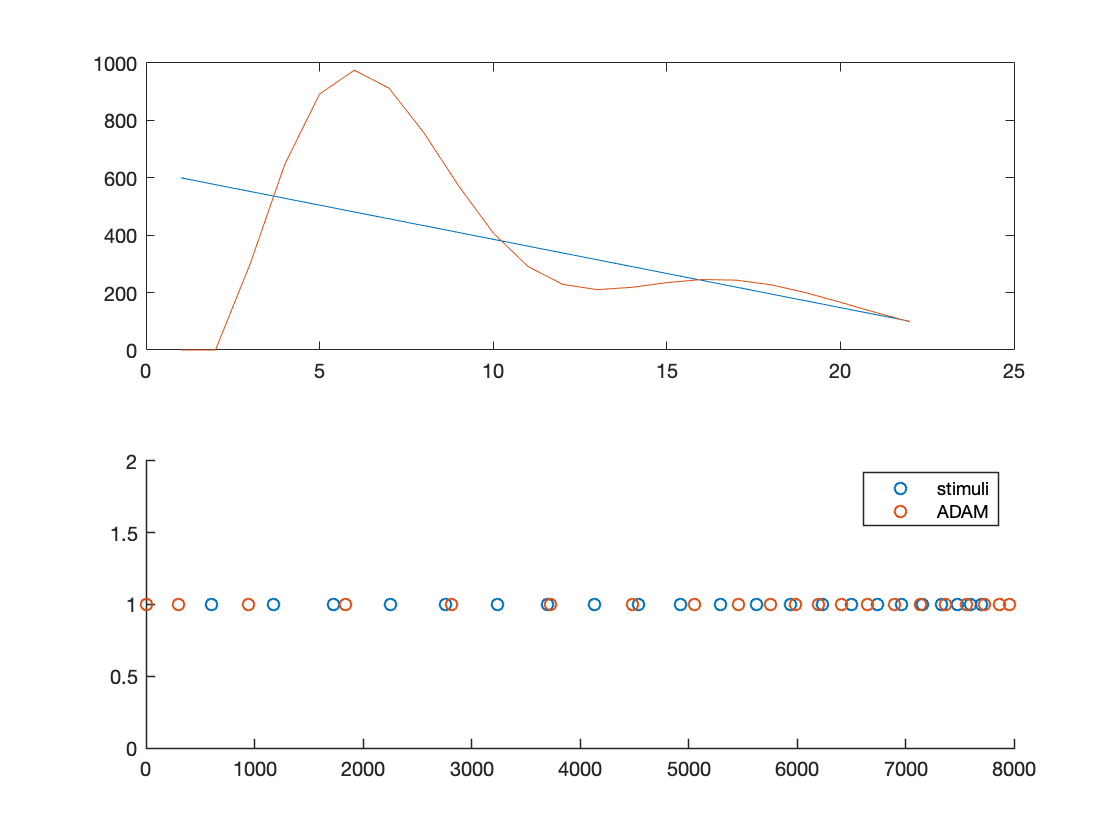

stim_times = [0 cumsum(stim_IOIs)];

T = zeros(1,N);        % timekeeper (interval)
t = zeros(1,N);        % ADAM's tap (timestamp)
asyn = zeros(1,N);     % asynchrony (t - stimtime)    

for n = 2:N

    asyn(n) = stim_times(n-1) - t(n-1);                     % most recent asynchrony

    t(n+1) = t(n) + ( T(n) + (alpha + beta) * asyn(n) );    % eq. (1)
    T(n+1) = T(n) + beta * asyn(n);                         % eq. (2)
    
end

% plot(diff(stim_times)), hold on; plot(diff(t)), hold off;

figure;
subplot(2,1,1)
plot(diff(stim_times)), hold on; plot(diff(t)), hold off;
subplot(2,1,2)
EK_dotplot(stim_times); hold on; EK_dotplot(t); legend('stimuli', 'ADAM'); hold off;

### Anticipation

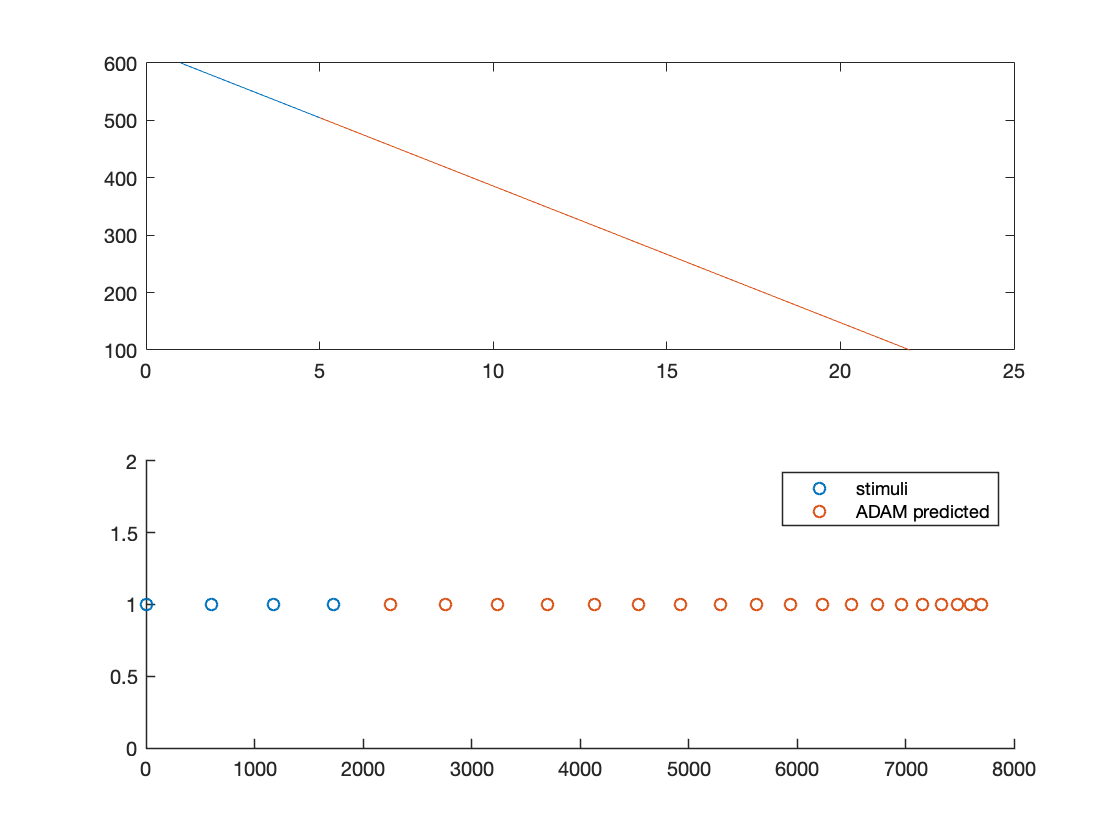

Int = zeros(1,N);
t_pred = zeros(1,N);

for n = 4:N

        fit = polyfit(n-2:n,diff(stim_times(n-3:n)),1); 
        Int(n+1) = fit(2) + fit(1) * (n+1); 
        t_pred(n+1) = stim_times(n)+ Int(n+1);

end 

t_pred(1:4) = NaN;
figure;
subplot(2,1,1)
plot(diff(stim_times)), hold on; plot(diff(t_pred)), hold off;
subplot(2,1,2)
EK_dotplot(stim_times); hold on; EK_dotplot(t_pred); legend('stimuli', 'ADAM predicted'); hold off;

### Joint internal model 

N = 34;
stim_IOIs = linspace(600,100,N);

alpha =0.4;
beta =0.1;
m =0.5;
gamma =0.4;

stim = [0 cumsum(stim_IOIs)];

T = zeros(1,N);        % timekeeper (interval)
t = zeros(1,N);        % ADAM's tap (timestamp)
asyn = zeros(1,N);     % asynchrony (t - stimtime)    
Int = zeros(1,N);
t_pred = zeros(1,N);
t_fin = zeros(1,N);

TK1 = normrnd(0,1,[1,N]);            % sampled from a normal dist
TK2 = normrnd(0,1,[1,N]);            % sampled from a normal dist
M = gamrnd(4,sqrt(25/4),[1,N]);               % drawn from gamma dist 

T(2:3) = stim_IOIs(1:2) + TK1(1:2);     % initialize timekeeper with first 2 stim intervals

for n = 2:N
   
    if n > 1 
    % adaptation ----------------------------------------
    asyn(n) = stim(n-1) - t(n-1);                     % most recent asynchrony
    
    t(n+1) = t(n) + ( T(n) + (alpha + beta) * asyn(n) + TK1(n));    % eq. (11)
    T(n+1) = T(n) + beta * asyn(n);                                 % eq. (12)
    end 

    if n > 3
    % anticipation --------------------------------------    
        fit = polyfit(n-2:n,diff(stim(n-3:n)),1);     
        IOI_pred(n+1) = fit(2) + fit(1) * (n+1);
        IOI_track(n+1) = t(n) - t(n-1);
        t_pred(n+1) = t(n) + (m * IOI_pred(n+1) + (1-m) * IOI_track(n+1)) + TK2(n);
    end
   
    % joint <3 -------------------------------------- 
    ASYN(n+1) = t(n+1) - t_pred(n+1);
    t_fin(n+1) = t(n+1) - ((1-gamma) * ASYN(n+1)) + M(n) - M(n-1);
end

figure;
subplot(2,1,1)
plot(diff(stim)), hold on; plot(diff(t_fin)), hold off;
subplot(2,1,2)
EK_dotplot(stim); hold on; EK_dotplot(t_fin); legend('stimuli', 'ADAM'); hold off;